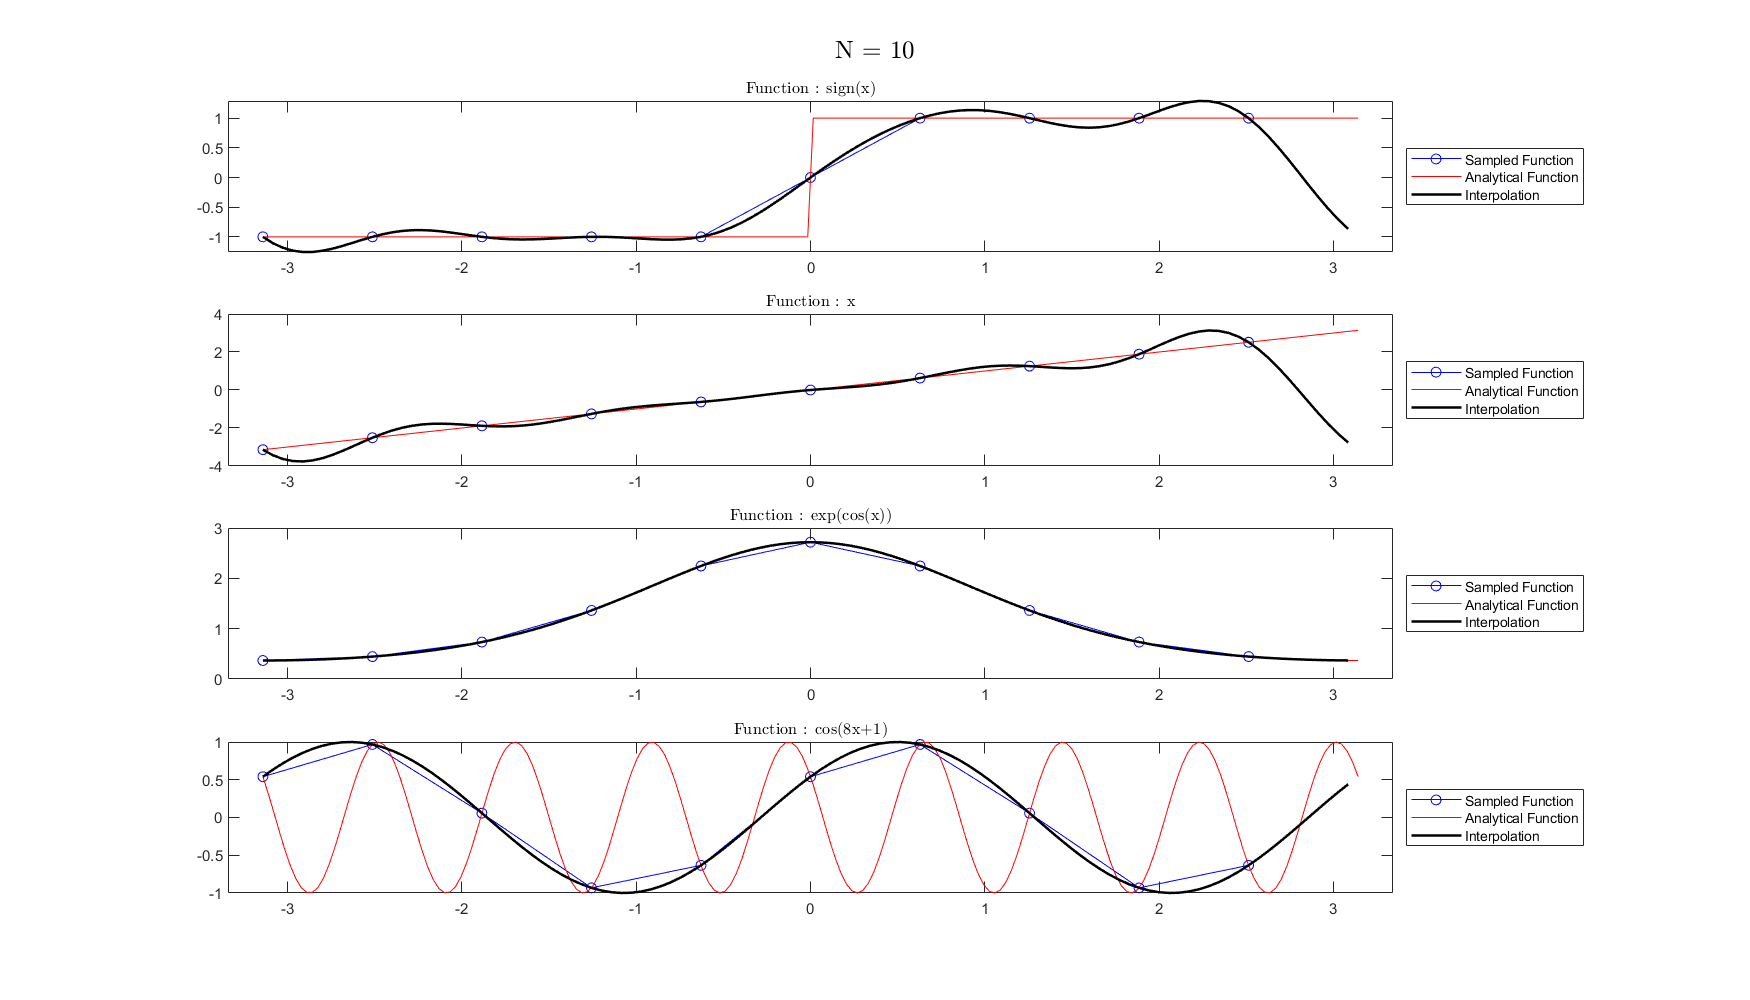

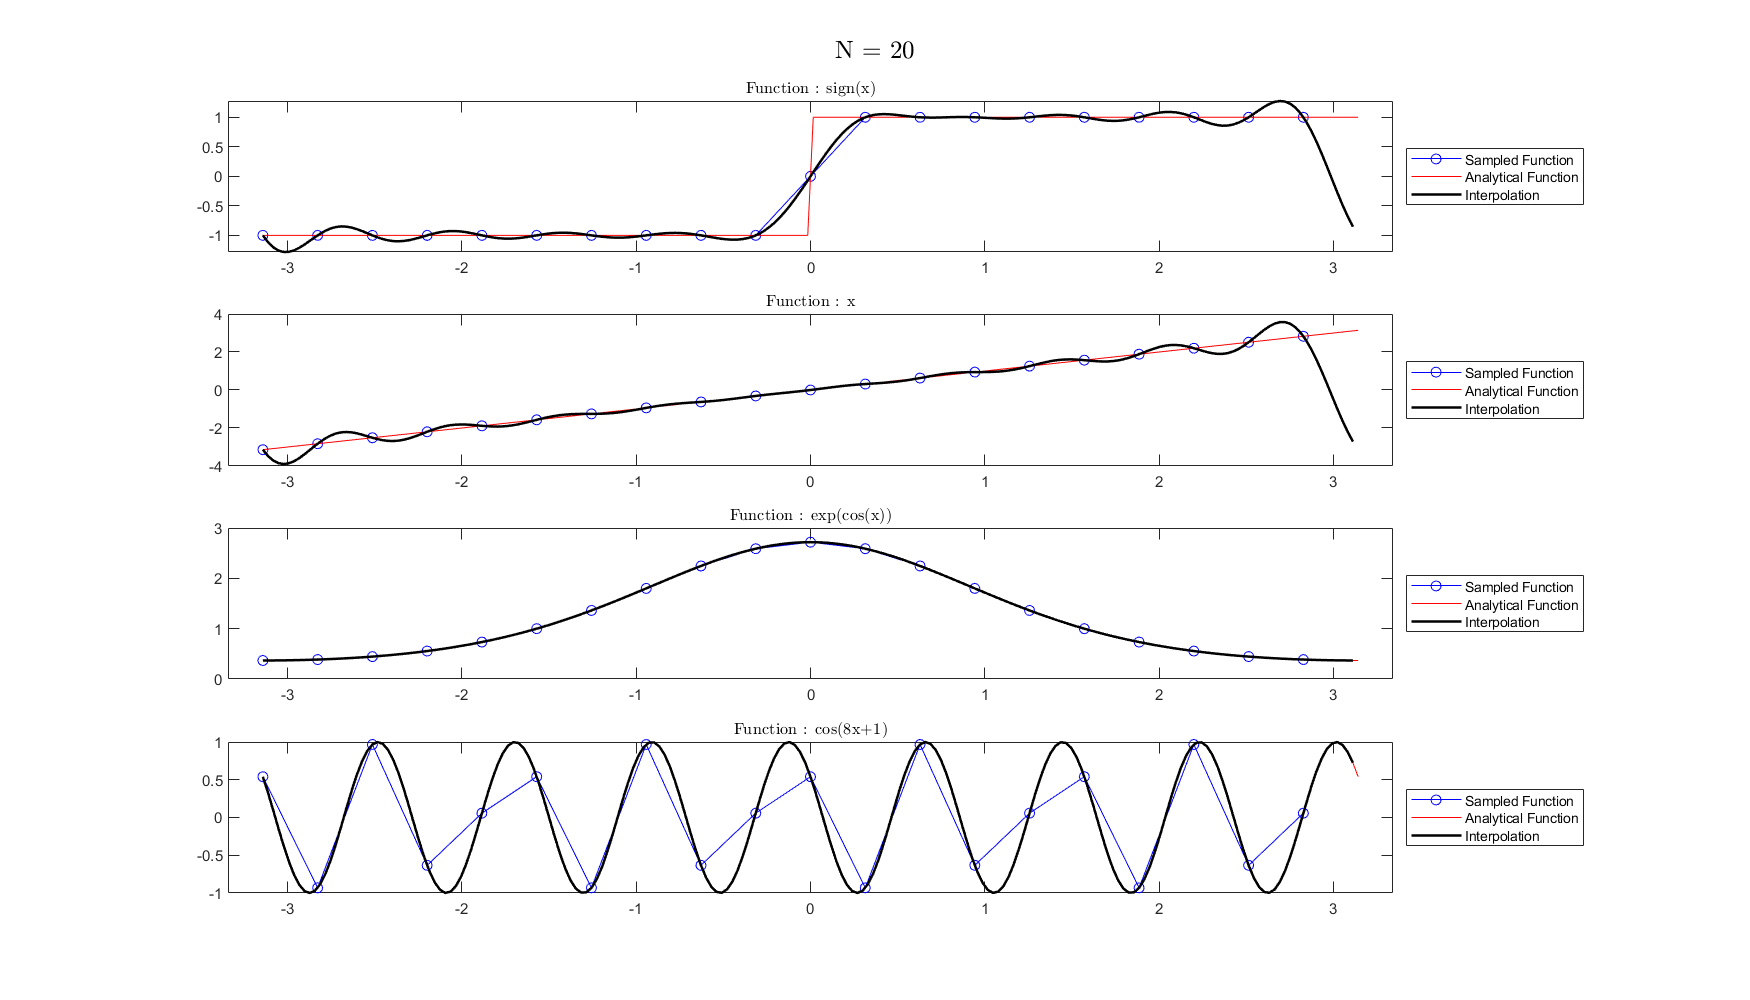

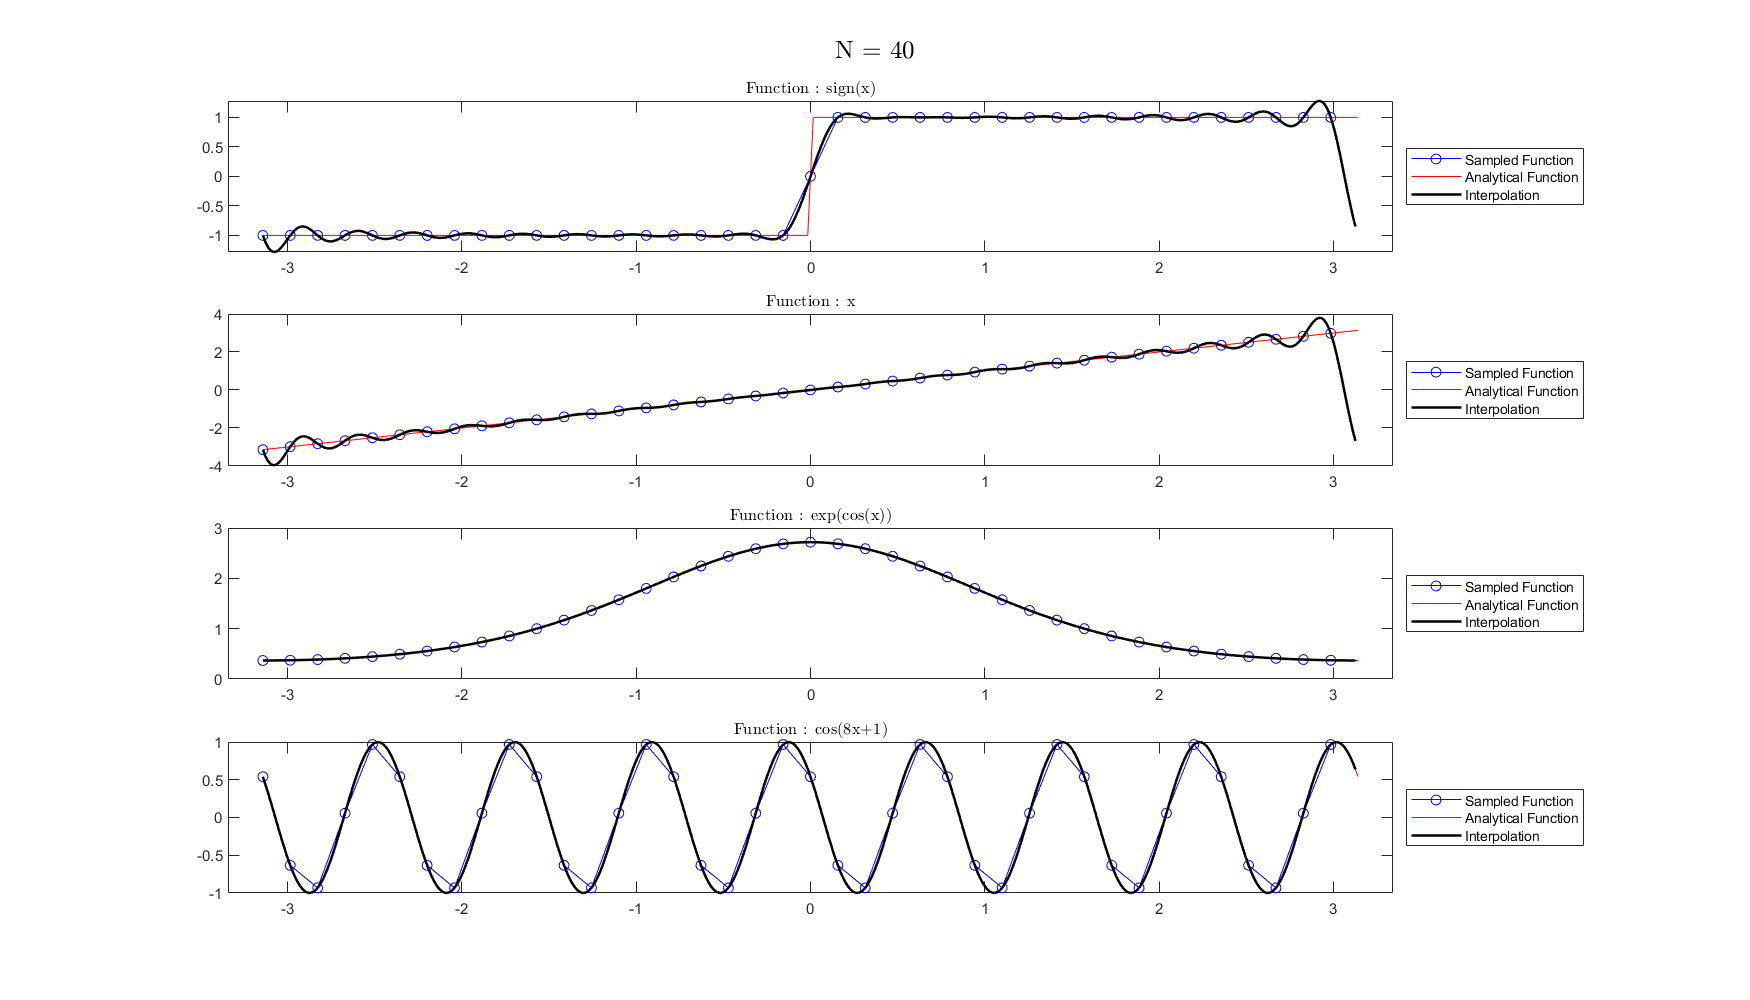

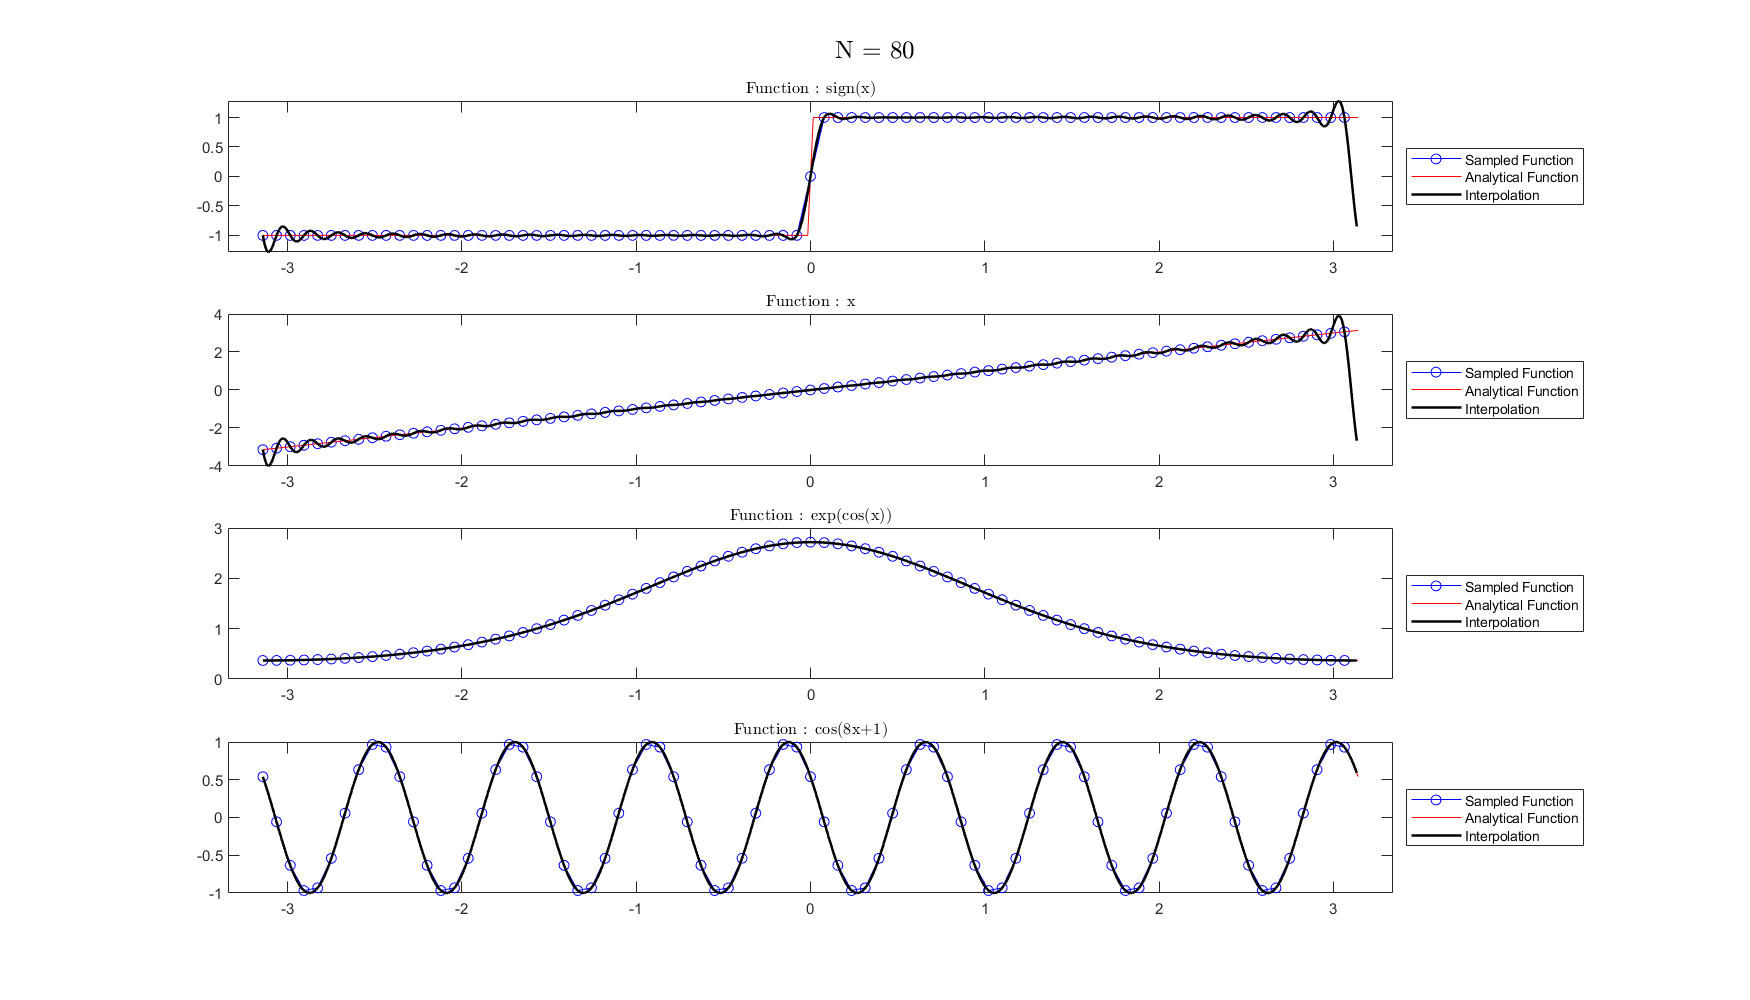

N = [10, 20, 40, 80];
M = 10.*N + 10;
functions = {@(x) sign(x), @(x) x, @(x) exp(cos(x)), @(x) cos(8*x+1)};
u_inv = zeros(max(M), length(functions));
function_names = {'sign(x)', 'x', 'exp(cos(x))', 'cos(8x+1)'};

% Adjust subplot spacing
subplotSpacing = 0.06; % Modify the spacing as needed
subplotOffset = 0.03; % Modify the offset as needed

for j=1:length(N)
    figure('Position', [100, 100, 1400, 800]);
    for l=1:length(functions)
    %{
    k = -(N(j)/2):1:(N(j)/2-1);
    temp = linspace(0, N(j)-1, N(j));
    h = (2.*pi)/N(j);
    xj = -pi + h.*(temp);
    
    kx = k'*xj;
    i = sqrt(-1);
    
    F = (1/N(j))*exp(-i*kx);
    
    uj = functions{j}(xj);
    uk = (F)*(uj');
    
    hl = (2.*pi)/M(j);
    temp = linspace(0, M(j)-1, M(j)); 
    yl = -pi + hl.*(temp);
    
    kyl = yl' * k;
    
    F_inv = exp(i*kyl);
    u_inv(1:M(j),j) = (F_inv)*(uk);
    %}
        temp = linspace(0, N(j)-1, N(j));
        h = (2.*pi)/N(j);
        xj = -pi + h.*(temp);
        uj = functions{l}(xj);
        hl = (2.*pi)/M(j);
        temp = linspace(0, M(j)-1, M(j)); 
        yl = -pi + hl.*(temp);
        
        u_inv(1:M(j), l) = (compute_F_inv(N(j), M(j))) * uj';
        
        % Create a subplot for the full function and its derivative
        subplot(length(functions), 1, l);
        
        % Plot the original function
        plot(xj, uj, '-ob', 'DisplayName', 'Sampled Function');
        xlim([-pi-0.2 +pi+0.2])
        hold on;
        
        tempar = linspace(-pi,pi,200);
        plot(tempar, functions{l}(tempar), 'r', 'DisplayName', 'Analytical Function');
        xlim([-pi-0.2 +pi+0.2])
        
        % Plot the interpolation
        plot(yl, u_inv(1:M(j),l), 'k', 'DisplayName', 'Interpolation','LineWidth',1.5);
        
        % Mark the sampled points on the original function
        %plot(xSamples, ySamples, 'o', 'MarkerFaceColor', 'g', 'DisplayName', 'Sampled Points');
        
        hold off;
        title(['Function ',': ', function_names{l}], 'Interpreter', 'latex');
        lgd = legend('Location', 'eastoutside');
        
        % Adjust subplot position for spacing
        %pos = get(gca, 'Position');
        %set(gca, 'Position', [pos(1) pos(2) pos(3) pos(4)-0.01]);
    end
    % Add an overall title
    sgtitle(['N = ', num2str(N(j))], 'Interpreter', 'latex');
end